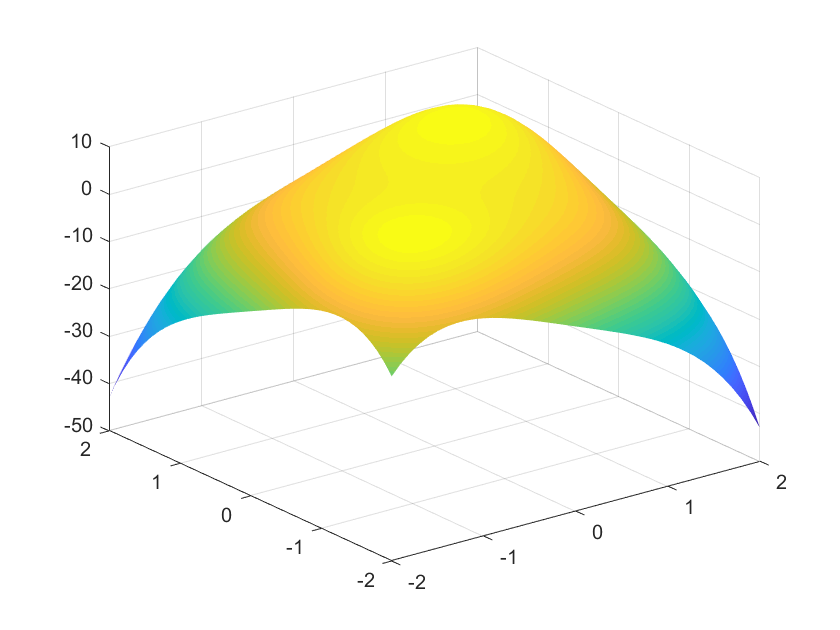

clear;clc;clf;
syms x y;%定义符号变量
x=-2:0.1:2;%定义x、y向量
y=x;

%绘制曲面图要先创建二维网络
[x,y]=meshgrid(x,y);
f=5-x.^4-y.^4+4.*x.*y;%一定要用点乘

surf(x,y,f)
shading interp

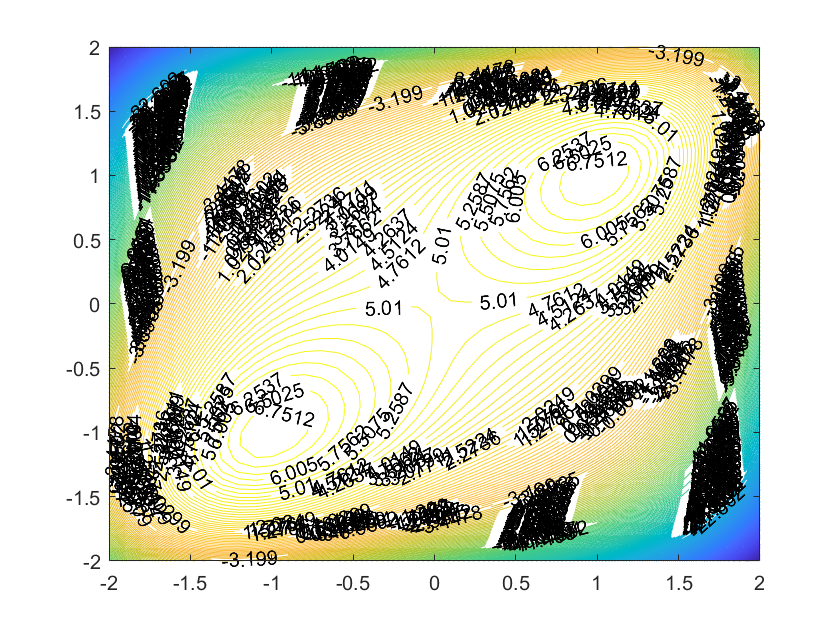

%这里要画200条等高线才能看出极值点位置
contour(x,y,f,200,'showtext','on')


%使用匿名函数，一定不要用点乘
%另外，由于要求极大值，所以原函数要先取反
f=@(t) -(5-t(1)^4-t(2)^4+4*t(1)*t(2));
[x,z]=fminsearch(f,[-0.5,-0.5])

x =         -0.999998161583788        -0.999959272795238


z =          -6.99999999032725


[x1,z1]=fminunc(f,[-0.5,-0.5])%比fminsearch更加精确


Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>


x1 =     -1    -1


z1 =     -7


fprintf("点(-0.5,-0.5)附近的极大值点为：(%0.3f,%0.3f,%0.3f)",x1(1),x1(2),-z1)

点(-0.5,-0.5)附近的极大值点为：(-1.000,-1.000,7.000)